# Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.1.5. Efecto del tipo de ventana de señal (v2.0)

### Objetivo

El objetivo de este ejercicio es la comprension del impacto del tipo de ventana de análisis en el espectro calculado de las señales. Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Desarrollo

Se dispone de una señal x(t), sinusoidal de frecuencia 1 Hz y duración de 10 periodos. Implemente un script en Matlab que realice las siguientes acciones:

- Borre variables, figuras y ventana de comandos:

clear all;
close all force;
clc;

- Genere una señal discreta x[n] muestreando x(t) a una frecuencia de 10Hz.

f            = [ 1 ];
numPeriods   = 10;
timeDuration = numPeriods / f;
amplitude    = [ 1 ];
phase        = [ 0 ];
fs           = 10;
[ x, numSamples, timeIndexes ] = generateSignal(fs, timeDuration, f, amplitude, phase);

- Genere un array de cadenas de caracteres que incluyan distintos tipos de ventanas ("boxcar", "triang", etc.) que soporta matlab. Pruebe con ventanas distintas para ver su efecto.

windowTypeArray = [ "boxcar" "triang" "blackman" ];
numWindowTypeSize  = length(windowTypeArray);

- Utilice la función wvtool() para evaluar las señales temporales y el espectro de cada una de las ventanas definidas en el array, y trate de predecir cuál será el efecto al usarlas para enventanar x[n] y calcular su FFT. Puede generar las ventanas usando la función window(windowType, numSamples). Note los parametros que indica la herramienta wvtool (leakage factor, relative sidelobe attenuation, mainlobe width) y relacionelo con la teoria vista en clase.

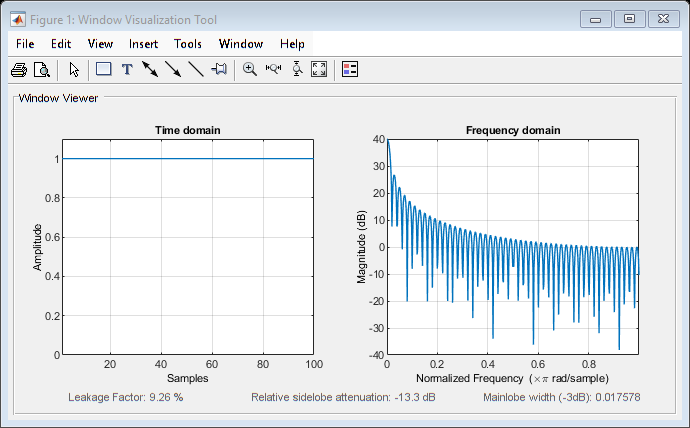

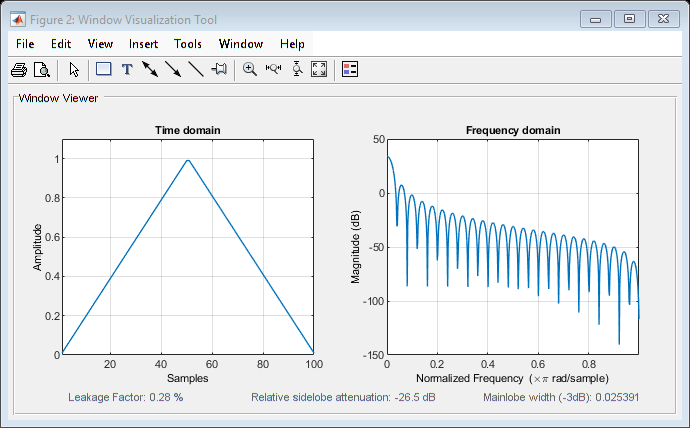

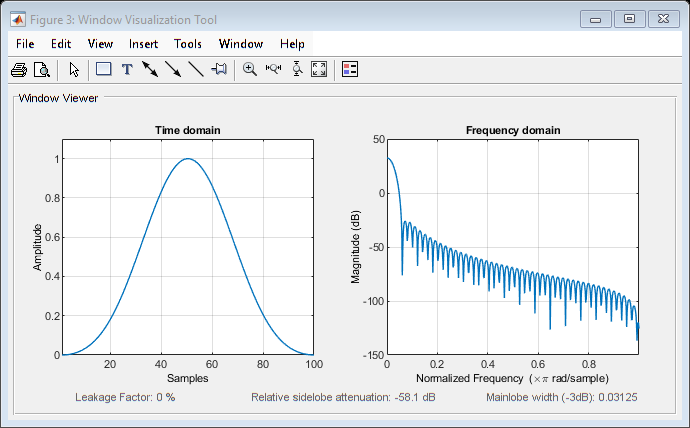

for idx = 1:numWindowTypeSize
    w = window(windowTypeArray(idx), numSamples);
    wvtool(window(windowTypeArray(idx), numSamples));
end

- Dentro de un bucle for que recorra el array de tipos de ventana, calcule el módulo de la fft resultante de aplicar cada una a la señal x[n], incluyendo cada uno en un subplot (use 2048 como tamaño de la FFT). En este caso haremos la normalizacion completa vista en clase. Escriba en un comentario breve en el código sus observaciones y justificación, incluyendo un comentario sobre los criterios importantes a tener en cuenta.

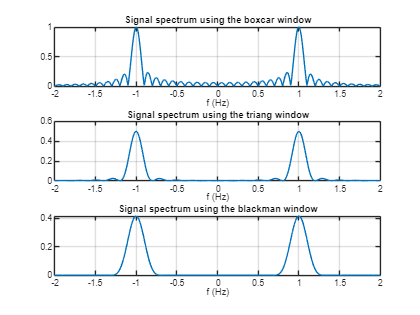

fftSize      = 2048;
fftSize_2    = fftSize/2;
figure
for idx = 1:numWindowTypeSize  
  subplot(numWindowTypeSize, 1, idx)
  xwindowed = x .* window(windowTypeArray(idx), numSamples)';
  fftX = 2 * fft(xwindowed, fftSize) / numSamples;
  fftX(1)    = fftX(1) / 2;
  fftX(end/2+1)  = fftX(end/2+1) / 2;

  fftIndexes = fs * (-fftSize_2:(fftSize_2-1)) / fftSize; % frequency values for each fft sample
  plot(fftIndexes, abs(fftshift(fftX)));
  title(['Signal spectrum using the '+ windowTypeArray(idx) + ' window' ]);
  xlabel('f (Hz)')
  xlim([-2 2]);
  grid on
end


% Observaciones y justificación: Describa lo que observe, discuta 
% si el resultado coincide con la prevision teorica e incluya un 
% comentario sobre los criterios
% que hay que considerar cuando se elige una ventana de analisis.

%Según la representacion de la figura 1, la ventana rectangular presenta el lobulo principal mas estrecho si se compara con las ventanas triangular (figura 2) y Blackman (figura 3),
%lo que permite distinguir mejor frecuencias fundamentales muy proximas entre sí, pero sus lobulos secundarios tienen mayor amplitud. Sin embargo, la ventana
%triangular, aunque ensancha el lobulo principal, reduce en mayor medida los lobulos secundarios. Por ultimo, la ventana Blackman presenta el lobulo principal mas
%ancho en comparacion a lo obtenido con las ventanas rectangular y triangular, pero consigue una mayor atenuacion de los lobulos secundarios que las otras dos ventanas.


% Al elegir una ventana hay que valorar la relacion entre la anchura del lobulo principal y la atenuacion de los lobulos secundarios.
% Un lobulo principal estrecho permite separar mejor frecuencias proximas, mientras que unos lobulos secundarios de menor amplitud
% reducen la presencia de energia en otras frecuencias distintas a las fundamentales. Por tanto, la ventana rectangular favorece la resolucion, la ventana Blackman reduce mas los
% lobulos secundarios y la ventana triangular ofrece un resultado intermedio.